# TokaLab Notebools - SimPla Module Guide

## Introduction

TokaLab is an open-access, open-source initiative dedicated to education, training, and open science in the field of nuclear fusion and tokamak physics, providing MATLAB and Python tools to build and explore virtual tokamak experiments. Within this framework, SimPla (*Simulated Plasma*) is the equilibrium module of TokaLab/VirtualLab. It computes the two-dimensional magnetic equilibrium of a plasma in a tokamak by solving the Grad–Shafranov equation, the force-balance equation that governs an axisymmetric plasma confined by a magnetic field.

Given a target plasma shape (the separatrix) and a model for the toroidal plasma current, SimPla solves for the poloidal flux ψ(R,Z) that is consistent with that shape, then derives from it the relevant physical fields: the toroidal and poloidal magnetic field components, the current density, and the kinetic and pressure profiles (electron/ion density, temperature, and pressure) mapped onto the magnetic surfaces.

SimPla supports two ways of posing the problem:

- **Fixed boundary**, where the plasma shape (separatrix) is imposed directly as a boundary condition. This is the default and simplest mode, well suited for fast, controlled, educational scenarios.

- **Free boundary**, where the plasma shape instead emerges from the interaction between the plasma current and the currents in the external poloidal field (PF) and central solenoid (CS) coils, which are solved for so that the resulting plasma edge approximates the target separatrix. This mode is closer to how a real tokamak equilibrium is actually established and controlled.

## **SimPla workflow**

SimPla organizes the equilibrium calculation around a small set of MATLAB classes that are built up in sequence, each one feeding the next.

The starting point is the `tokamak` class. It holds everything that describes the device and the scenario you want to simulate: the machine geometry (major and minor radius, vessel wall), the target plasma scenario (the shape of the separatrix and the model used for the toroidal current), and the kinetic profiles (density and temperature) that will later be mapped onto the equilibrium.

From there, the `geometry` class builds the actual computational grid in the (R, Z) plane and works out which grid points lie inside the vessel wall, producing the mask that all subsequent calculations are restricted to.

These two pieces are then passed to the `equilibrium` class, the core of SimPla. It first constructs the target separatrix from the scenario parameters, then solves the Grad–Shafranov equation iteratively until the poloidal flux ψ(R,Z) converges. Once converged, it locates the O-point and X-point, derives the last closed flux surface (LCFS), and computes the resulting magnetic field, current density, and kinetic/pressure profiles.

This main chain (`tokamak` → `geometry` → `equilibrium)` is enough to obtain a fixed-boundary equilibrium, since the separatrix shape is just imposed directly as a constraint.

If instead you want a free-boundary equilibrium, one extra branch comes into play: the `coils` class, which holds the geometry of the poloidal field (PF) and central solenoid (CS) coils. In that case the coil currents become additional unknowns and are solved together with ψ so that the resulting plasma edge approximates the target separatrix, rather than having that shape imposed outright.

### **Prerequisites**

To use the TokaLab packages, it is important to run the function `VirtualLab_init()`, so that all the required paths are added to your MATLAB workspace.

% add all TokaLab paths to the workspace
VirtualLab_init()

new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/apps
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/docs
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/DataGen_MATLAB
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/DataGen_MATLAB/functions_dg
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/DataGen_MATLAB/config_dg
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/examples
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_fusion\01 - github repositories\VirtualLab\VirtualLab_MatLab/SimPla_MATLAB
new added path : C:\Users\ricca\OneDrive\PJ - 02 - TOKALAB_

### Setting up the device: the `tokamak` class

The `tokamak` class collects all the device-specific information needed before solving for an equilibrium: the machine geometry, the target scenario, and the kinetic profiles. We build it up one piece at a time.

% initialise the tokamak class
tok = tokamak;

We start by loading the machine geometry: major and minor radius, and the vessel wall contour. If no machine name is given, the default TokaLab device is used.

% load the machine geometry (default: TokaLab)
tok = tok.machine_upload();

TokaLab


disp(tok)

  tokamak with properties:

    machine: "TokaLab"
         R0: 6
          a: 2
       wall: [1×1 struct]
       grid: [1×1 struct]
      coils: []
     config: []



Next, we load the scenario: the target shape of the separatrix and the model used for the toroidal current density. This is also where you would change configuration index to switch between, for example, a single-null and a double-null plasma shape.

% load the target scenario (separatrix shape + current model)
tok = tok.scenario_upload();
disp(tok.config.separatrix)

     scenario: 1
       method: 1
           k1: 1.7000
           k2: 2
           d1: 0.5000
           d2: 0.5000
    gamma_n_1: 0
    gamma_n_2: 1.0472
    gamma_p_1: 0
    gamma_p_2: 0.5236
            a: 2
           R0: 6
           Z0: 0



disp(tok.config.toroidal_current)

     method: 1
         Bt: 5
         Ip: -12000000
    alpha_1: 2
    alpha_2: 2
     beta_0: 0.5000
     lambda: 1



Finally, we load the kinetic profiles: the models used to compute electron/ion density and temperature once the equilibrium is solved.

% load the kinetic profile model
tok = tok.kinetic_upload();
disp(tok.config.kinetic)

    scenario: 1
      method: 1
          a1: 6
          a2: 3
          n0: 1.0000e+20
        nsep: 1.0000e+17



If you want to change one or more parameters, you can do it directly from the tok.config structure. For example, if you want a different minor radius, you can write: 

% tok.config.separatrix.a = a_new 

### Building the computational domain: the `geometry` class

Once the tokamak class has been set up, the `geometry` class uses that information to build the actual computational grid in the (R, Z) plane, and to work out which grid points lie inside the vessel wall. This grid and wall mask are what every later calculation (the Grad–Shafranov solver included) is built on.

% initialise the geometry class
geo = geometry;

We import the geometry information stored in the `tokamak` object (major/minor radius, wall contour) into the `geometry` class.

% import geometry information from the tokamak class
geo = geo.import_geometry(tok);
disp(geo)

  geometry with properties:

           R0: 6
            a: 2
            R: []
            Z: []
           dR: []
           dZ: []
         grid: [1×1 struct]
         wall: [1×1 struct]
    operators: []



Next, we build the actual (R, Z) computational grid.

% build the computational grid
geo = geo.build_geometry();

Finally, we compute the mask of grid points that lie inside the vessel wall. This is what restricts later calculations (currents, fields, profiles) to the physically meaningful region.

% compute the inside-wall mask
geo = geo.inside_wall();

We can now visualize the wall contour we just loaded, as a first sanity check.

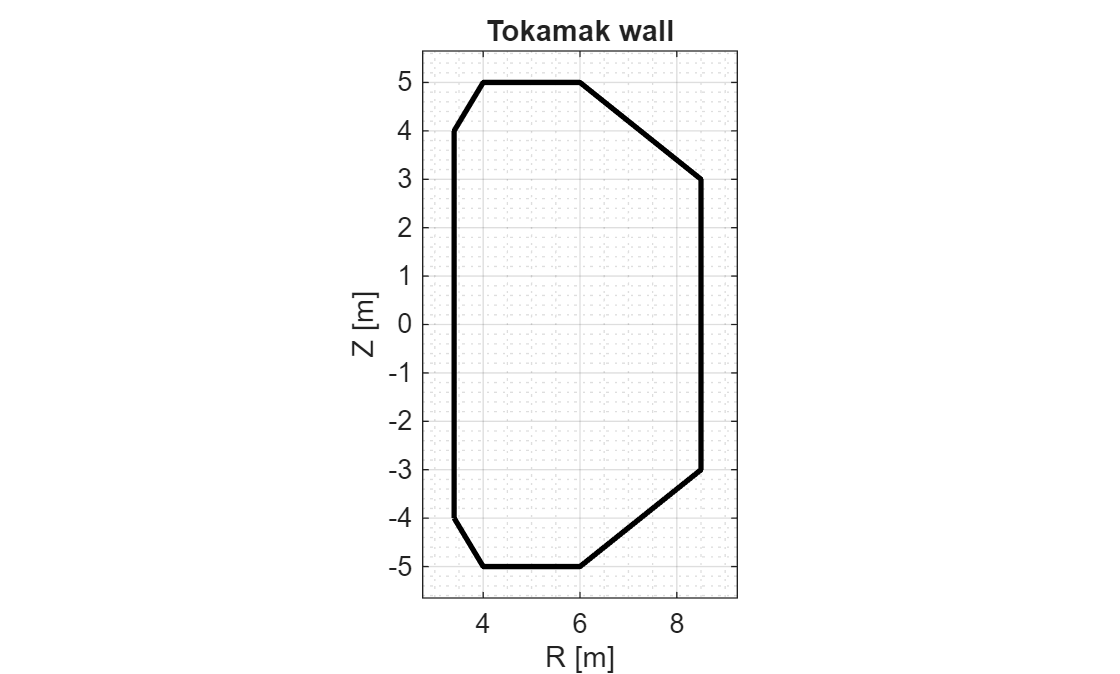

% plot the vessel wall
figure
geo.plot_wall()
axis equal
xlim([min(geo.grid.Rg,[],"all") max(geo.grid.Rg,[],"all")])
ylim([min(geo.grid.Zg,[],"all") max(geo.grid.Zg,[],"all")])
title("Tokamak wall")

### Defining and solving the equilibrium: the `equilibrium` class

The `equilibrium` class is the core of SimPla. It takes the geometry and the scenario configuration, builds the target plasma shape (the separatrix), solves the Grad–Shafranov equation, and finally computes all the fields and profiles describing the equilibrium.

% initialise the equilibrium class
equi = equilibrium;

We import the geometry and the scenario configuration (separatrix shape, current model) into the equilibrium class.

% import geometry and scenario configuration
equi = equi.import_configuration(geo,tok.config);
equi = equi.import_classes();

Before solving anything, we build the target separatrix: the plasma boundary that the fixed-boundary solver will impose as a constraint.

% build the target separatrix
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);

It is good practice to check the target separatrix against the vessel wall before solving, to make sure the plasma shape we are aiming for actually fits inside the machine.

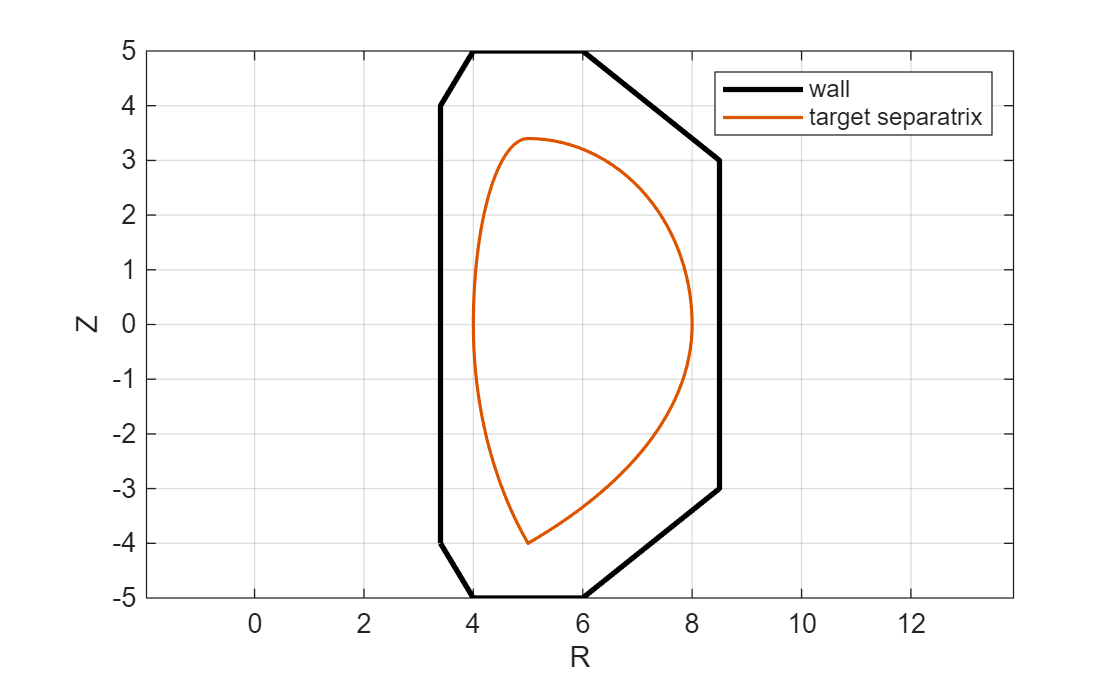

% compare the target separatrix with the wall
figure
geo.plot_wall()
hold on
equi.plot_separatrix();
axis equal
legend("wall","target separatrix")

We can now solve the Grad–Shafranov equation. The solver iterates on the poloidal flux ψ(R,Z) until it converges, using the tolerances and maximum number of iterations stored in `equi.config.GSsolver`.

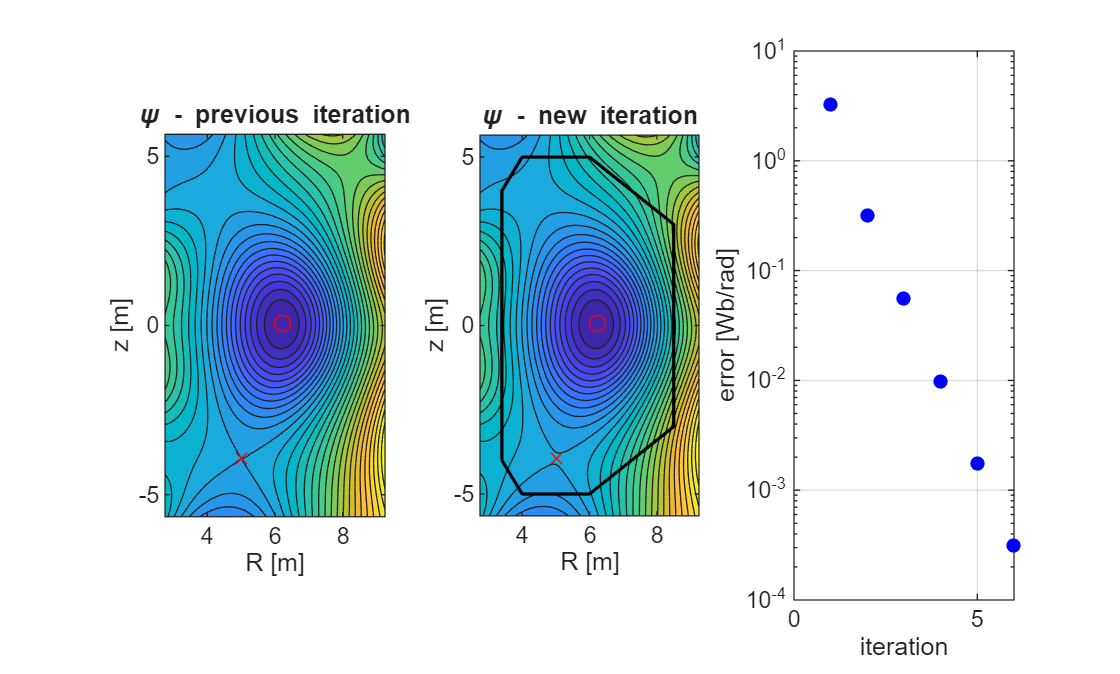

% solve the equilibrium (fixed boundary)
equi = equi.solve_equilibrium();

Once ψ has converged, we still need to locate the O-point and X-point and derive the last closed flux surface (LCFS) from them.

% locate O-point, X-point, and the LCFS
equi = equi.equi_pp();

Finally, we compute the remaining physical quantities — magnetic field, current density, and kinetic/pressure profiles, mapped onto the equilibrium.

% compute MHD and kinetic profiles
equi = equi.compute_profiles();

### Plotting the results

Now that the equilibrium has been solved, we can look at the resulting fields. `equilibrium.plot_fields(field_name, equi_lines)` plots any computed quantity on the (R, Z) grid, optionally overlaying flux surfaces.

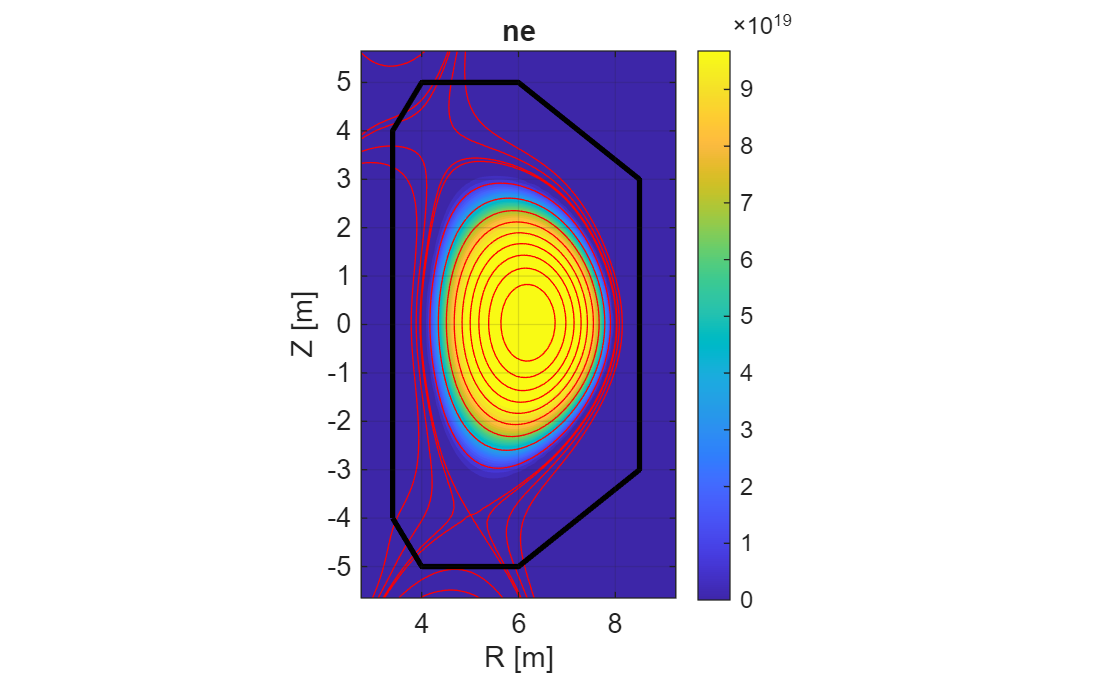

% normalised poloidal flux, with flux surfaces overlaid
figure
equi.plot_fields("ne",1)
hold on
geo.plot_wall()

The flux surface at ψₙ = 1 is, by construction, the LCFS we located in the previous step — the boundary between the confined plasma and the scrape-off region.

We can compare several fields side by side in the same figure, to see at a glance how the magnetic field, the current density, and the kinetic profiles are all shaped by the same equilibrium.

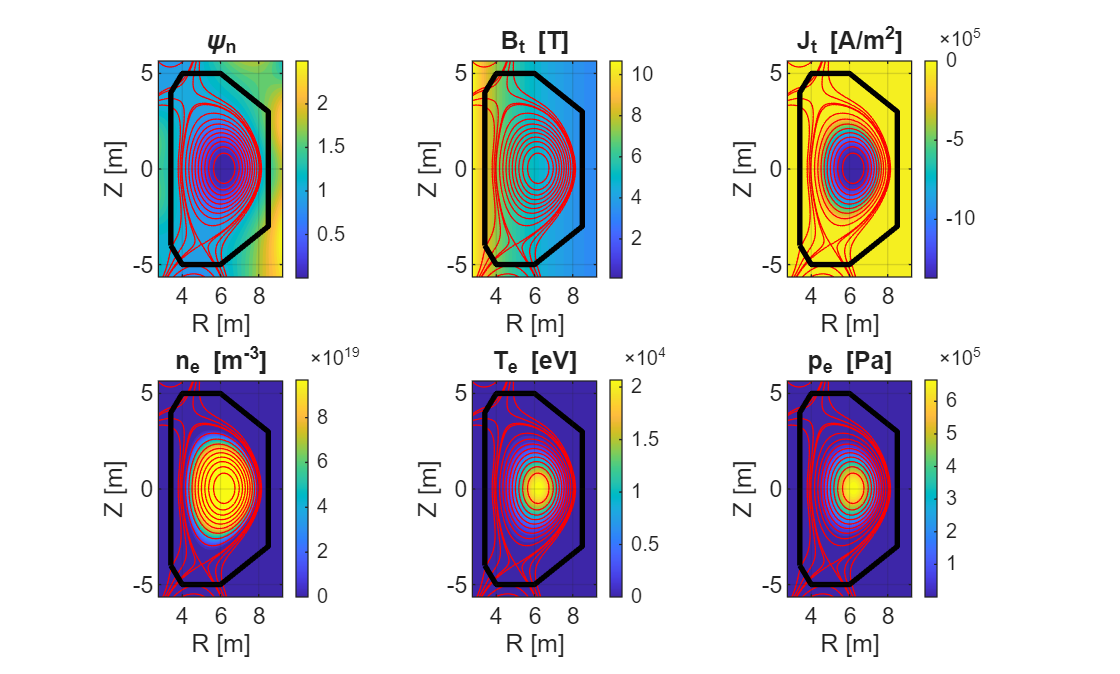

figure

subplot(2,3,1)
equi.plot_fields("psi_n",1)
hold on; geo.plot_wall()
title("\psi_n")

subplot(2,3,2)
equi.plot_fields("Bt",1)
hold on; geo.plot_wall()
title("B_t [T]")

subplot(2,3,3)
equi.plot_fields("Jt",1)
hold on; geo.plot_wall()
title("J_t [A/m^2]")

subplot(2,3,4)
equi.plot_fields("ne",1)
hold on; geo.plot_wall()
title("n_e [m^{-3}]")

subplot(2,3,5)
equi.plot_fields("Te",1)
hold on; geo.plot_wall()
title("T_e [eV]")

subplot(2,3,6)
equi.plot_fields("pe",1)
hold on; geo.plot_wall()
title("p_e [Pa]")

## Class Specifications

### Class `tokamak`

The class `tokamak` is used to define the machine to be used and the (standard) scenario to upload. New machines and geometries are expected to be implemented inside this script, by allowing the rest of the pipeline (geometry and equilibrium) machine independent. 

The class tokamak contains six properties and three main methods. 

**Properties: **

**Functions: **

- *machine_upload(machine)*

- *scenario_upload(separatrix,Jt_method)*

- *kinetic_upload()*

To generate tokamak documentation, please type the following command into the workspace: 

doc tokamak

while using help you can see information for both the class: 

 help tokamak

  Class tokamak
 
  This is the class used to define the machine to be used (new machines
  can be easily added, see documentation and example 4), the scenario
  (target separatrix), and the methodology to simulate or map kinetic
  profiles on the magnetic surfaces.
 
  Write help tokamak.(properties) to see info about each property
  Write doc tokamak to generate the MATLAB documentation for the
  tokamak class

    Documentation for tokamak



its properties:

help tokamak.machine

 machine -  Tokamak name



help tokamak.R0

 R0 -  Major radius of the tokamak



help tokamak.a

 a -  Minor radius of the tokamak



help tokamak.wall

 wall -  structure containing wall information



help tokamak.grid

 grid -  grid of the geometry



help tokamak.config

 config -  this structure contains various configuration and parameters for equilibrium



and methods (functions):

help tokamak.machine_upload

  Method machine_upload - tokamak/machine_upload(machine)
 
  machine - it indicates the machine to be uploaded.
  if machine is not used, tokamak/machine_upload(), machine = "Tokalab" is used
 
  Then, it uploaded the machine specific geometry (major and
  minor radii, grid information, and wall contours).



help tokamak.scenario_upload

  Method scenario_upload - tokamak/scenario_upload(separatrix, Jt_method)
 
  separatrix - is a number (e.g. 1) which indicates the
  scenario to be used (see Tokalab_Scenario as example)
 
  Jt_method - is a number (e.g.) which defines the
  functionality between toroidal current and poloidal flux
  (see Tokalab_Scenario as example)
 
  All this machine and scenario information are stored inside
  tokamak.config



help tokamak.kinetic_upload

  Method kinetic_upload - tokamak/kinetic_upload()
 
  It uploads the scenario and tokamak specific paramters inside
  the tokamak.config variable.



To use the tokamak class in your script, you need to initialise the class. Here, our class tokamak will be initialised with the name tok.

tok = tokamak

tok =   tokamak with properties:

    machine: []
         R0: []
          a: []
       wall: []
       grid: []
      coils: []
     config: []


By pressing disp(tok) in your command window you will see that tok now contains the properties, but they are empty. Therefore, you need to upload you machine. If you are using TokaLab standard geometry, you have two options: 

Option 1. 

tok = tok.machine_upload("TokaLab")

TokaLab


tok =   tokamak with properties:

    machine: "TokaLab"
         R0: 6
          a: 2
       wall: [1×1 struct]
       grid: [1×1 struct]
      coils: []
     config: []


Option 2. 

tok = tok.machine_upload()

TokaLab


tok =   tokamak with properties:

    machine: "TokaLab"
         R0: 6
          a: 2
       wall: [1×1 struct]
       grid: [1×1 struct]
      coils: []
     config: []


Once machine_upload is used, some of the properties are uploaded in the class tokamak (tok). You can digit disp(tok) to see the new information. 

disp(tok)

  tokamak with properties:

    machine: "TokaLab"
         R0: 6
          a: 2
       wall: [1×1 struct]
       grid: [1×1 struct]
      coils: []
     config: []



Then, you have to upload the scenario, which takes as input the variable separatrix and Jt_method. Both are expected to be integers numbers (1, 2, etc.) and each number defines a separatrix and how the toroidal current is mapped as a function of the poloidal flux.   

tok = tok.scenario_upload(1,1)

tok =   tokamak with properties:

    machine: "TokaLab"
         R0: 6
          a: 2
       wall: [1×1 struct]
       grid: [1×1 struct]
      coils: []
     config: [1×1 struct]


Then, the *kinetic_upload* function should be used to update kinetic profile relative information. Analogously to *scenario_upload*, *kinetic_upload* is though to take a numeric input (*kinetic*) which defines one standard configuration. 

However, at the moment, only one configuration is implemented and therefore you have just to run the empty one. 

tok = tok.kinetic_upload()

tok =   tokamak with properties:

    machine: "TokaLab"
         R0: 6
          a: 2
       wall: [1×1 struct]
       grid: [1×1 struct]
      coils: []
     config: [1×1 struct]


### Class `geometry`

This class allows to prepare the computational geometry for SimPla (and other module dependent on SimPla, like SynDiag). This class is machine independent since takes the input from the class `tokamak`.

The class `geometry` contains six properties and three main methods. 

**Properties: **

**Functions: **

- *import_geometry(tokamak)*

- *build_geometry( )*

- *inside_wall( )*

- *geo_operator( )*

Similarly to the class tokamak, you need to initialise the geometry class:

geo = geometry

geo =   geometry with properties:

           R0: []
            a: []
            R: []
            Z: []
           dR: []
           dZ: []
         grid: []
         wall: []
    operators: []


Then, import_geometry function imports fundamental geometric parameters (`R0`, `a`, `grid`, `wall`) from the `tokamak` class. 

geo = geo.import_geometry(tok)

geo =   geometry with properties:

           R0: 6
            a: 2
            R: []
            Z: []
           dR: []
           dZ: []
         grid: [1×1 struct]
         wall: [1×1 struct]
    operators: []


Therefore, with build_geometry you construct the 2D computational grid used for equilibrium and other modules (e.g. SynDiag). It uses parameters such as `R0`, `a`, and grid hyperparameters (`N_R`, `N_Z`, `wall_thick`, `kappa_max`) to generate `R`, `Z`, and the mesh structures `Rg`, `Zg`.

geo = geo.build_geometry()

geo =   geometry with properties:

           R0: 6
            a: 2
            R: [2.7500 2.8442 2.9384 3.0326 3.1268 3.2210 3.3152 3.4094 3.5036 3.5978 3.6920 3.7862 3.8804 3.9746 4.0688 4.1630 4.2572 4.3514 4.4457 4.5399 4.6341 4.7283 4.8225 4.9167 5.0109 5.1051 5.1993 5.2935 5.3877 5.4819 5.5761 … ] (1×70 double)
            Z: [-5.6500 -5.5070 -5.3639 -5.2209 -5.0778 -4.9348 -4.7918 -4.6487 -4.5057 -4.3627 -4.2196 -4.0766 -3.9335 -3.7905 -3.6475 -3.5044 -3.3614 -3.2184 -3.0753 -2.9323 -2.7892 -2.6462 -2.5032 -2.3601 -2.2171 -2.0741 -1.9310 … ] (1×80 double)
           dR: 0.0942
           dZ: 0.1430
         grid: [1×1 struct]
         wall: [1×1 struct]
    operators: [1×1 struct]


By using inside_wall, you create a logical mask identifying points inside the tokamak wall. The mask is stored in `wall.inside` and is used in computational routines and visualization tasks.

geo = geo.inside_wall()

geo =   geometry with properties:

           R0: 6
            a: 2
            R: [2.7500 2.8442 2.9384 3.0326 3.1268 3.2210 3.3152 3.4094 3.5036 3.5978 3.6920 3.7862 3.8804 3.9746 4.0688 4.1630 4.2572 4.3514 4.4457 4.5399 4.6341 4.7283 4.8225 4.9167 5.0109 5.1051 5.1993 5.2935 5.3877 5.4819 5.5761 … ] (1×70 double)
            Z: [-5.6500 -5.5070 -5.3639 -5.2209 -5.0778 -4.9348 -4.7918 -4.6487 -4.5057 -4.3627 -4.2196 -4.0766 -3.9335 -3.7905 -3.6475 -3.5044 -3.3614 -3.2184 -3.0753 -2.9323 -2.7892 -2.6462 -2.5032 -2.3601 -2.2171 -2.0741 -1.9310 … ] (1×80 double)
           dR: 0.0942
           dZ: 0.1430
         grid: [1×1 struct]
         wall: [1×1 struct]
    operators: [1×1 struct]


The function *geo_operator *can be used to generate a boundary operator matrix and associated indices. This matrix identifies grid points on the boundary of the computational domain and is used by solvers (e.g. Grad–Shafranov equation). See class **equilbrium **and some **SimPla** related examples for deeper details. 

### Class `equilibrium`

The `equilibrium` class is the core computational engine of the **SimPla** module within *TokaLab*, dedicated to solving the **magnetohydrostatic equilibrium (Grad–Shafranov equation)** in tokamak-like configurations.

Its main goal is to provide a **modular and open framework** to:

- compute the magnetic equilibrium from a **target separatrix** and configurable input parameters,

- generate self-consistent magnetic and physical fields under MHD assumptions,

**Properties (structures): **

**Properties (Main quantities): **

**Functions:**

- `import_configuration(geo, config)`

- `import_classes()`

- `solve_equilibrium(psi)`

- `equi_pp()`

- `equi_pp2()`

- `compute_profiles()`

- `CriticalPoints(Ip, R, Z, inside_wall, Psi)`

- `find_LCFS()`

- `q_profile()`

- `plot_separatrix()`

- `plot_fields(field, equi_lines)`

Similarly to the class `geometry`, you first need to initialise the equilibrium class:

equi = equilibrium

equi =   equilibrium with properties:

              geo: []
           config: []
       separatrix: []
            utils: []
    toroidal_curr: []
            const: []
         MHD_prof: []
         kin_prof: []
         Rad_prof: []
      profiles_1D: []
         GreenFun: []
              psi: []
              Psi: []
            psi_n: []
               Jt: []
               Jr: []
               Jz: []
               Bt: []
               Br: []
               Bz: []
                p: []
               F2: []
               ne: []
               ni: []
             Zeff: []
               Te: []
               Ti: []
               pe: []
               pi: []
              Rad: []
           Opoint: []
           Xpoint: []
             LCFS: []
          psi_ref: []
            q_psi: []


The function `import_configuration` imports the geometry (`geo`) and solver configuration (`config`) parameters. It sets default parameters for the Grad-Shafranov solver, such as maximum iterations, tolerances, update rate, and plotting options.

equi = equi.import_configuration(geo, tok.config);

Next, `import_classes` loads all supporting classes needed for the equilibrium calculation: `separatrix` (target separatrix), `utils` (differential operators), `toroidal_curr` (toroidal current methods), `constants`, `MHD_prof` (pressure and F² evaluation), and `kin_prof` (kinetic profiles).

equi = equi.import_classes();

The target separatrix is then defined using the `build_separatrix` method of the `separatrix` class. This prepares the desired flux surface geometry for the equilibrium solver.

equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix, equi.geo);

The equilibrium is computed by solving the Grad-Shafranov equation with `solve_equilibrium`. This method iteratively computes the poloidal flux (`psi`), identifies critical points (O-point and X-point), and updates the toroidal current until convergence is achieved.

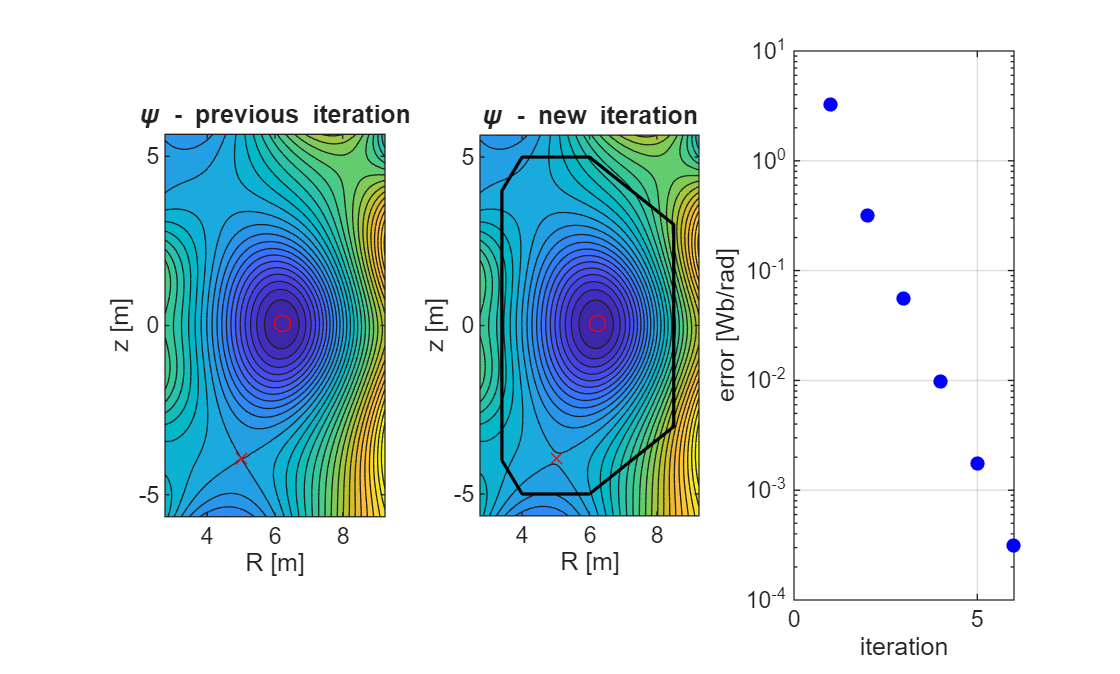

equi = equi.solve_equilibrium();

Post-processing with `equi_pp2` evaluates the normalized poloidal flux (`psi_n`), locates the O-point and X-point, and determines the Last Closed Flux Surface (LCFS). This prepares the equilibrium for profile evaluation and visualization.

equi = equi.equi_pp2();

Finally, `compute_profiles` calculates MHD quantities (pressure, F², magnetic fields, currents) and kinetic profiles (densities, temperatures, pressures), storing them in the class properties for further analysis and plotting.

equi = equi.compute_profiles();

Finally, you can plot your field by using a plotting function: 

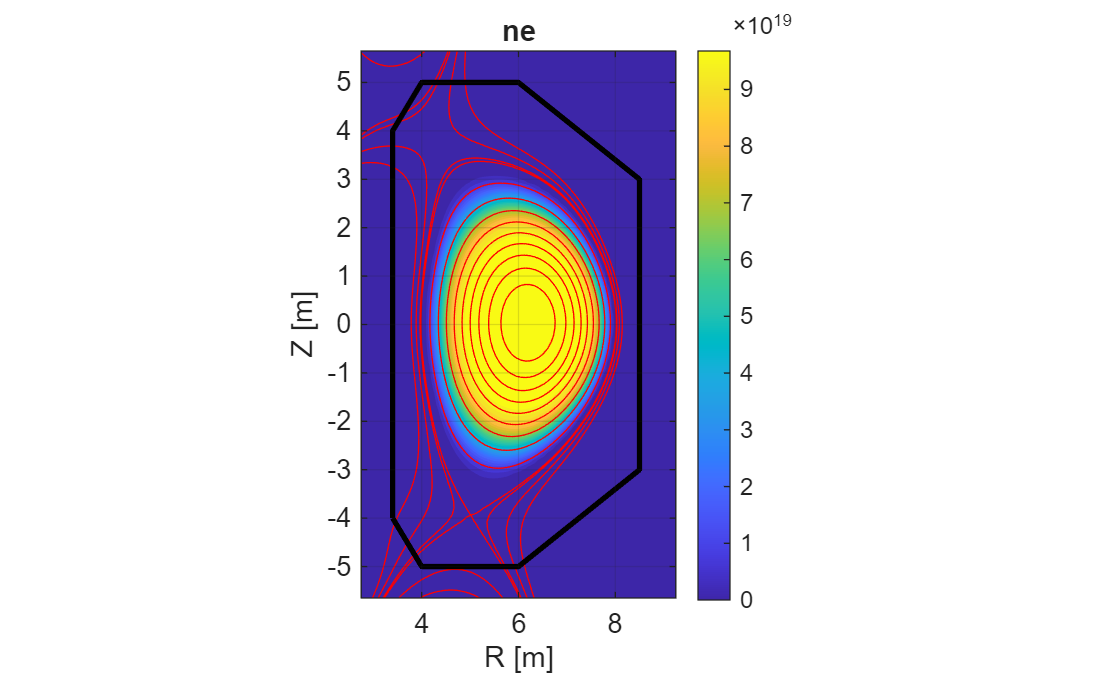

figure(2)
clf
equi.plot_fields("ne",1)
hold on
equi.geo.plot_wall

## Examples

### Changing the target separatrix

The shape of the target separatrix is entirely controlled by the parameters stored in `tok.config.separatrix` (and, after `import_configuration`, mirrored in `equi.config.separatrix`). Changing one of these parameters and rebuilding the separatrix is the quickest way to explore different plasma shapes without touching anything else in the workflow.

Recall that the separatrix is built with:

equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);

Any change to `equi.config.separatrix` must be followed by a new call to `build_separatrix` to take effect.

#### Moving the separatrix

The parameters `R0` and `Z0` set the geometric center of the separatrix. Let's shift it radially outward and vertically upward.

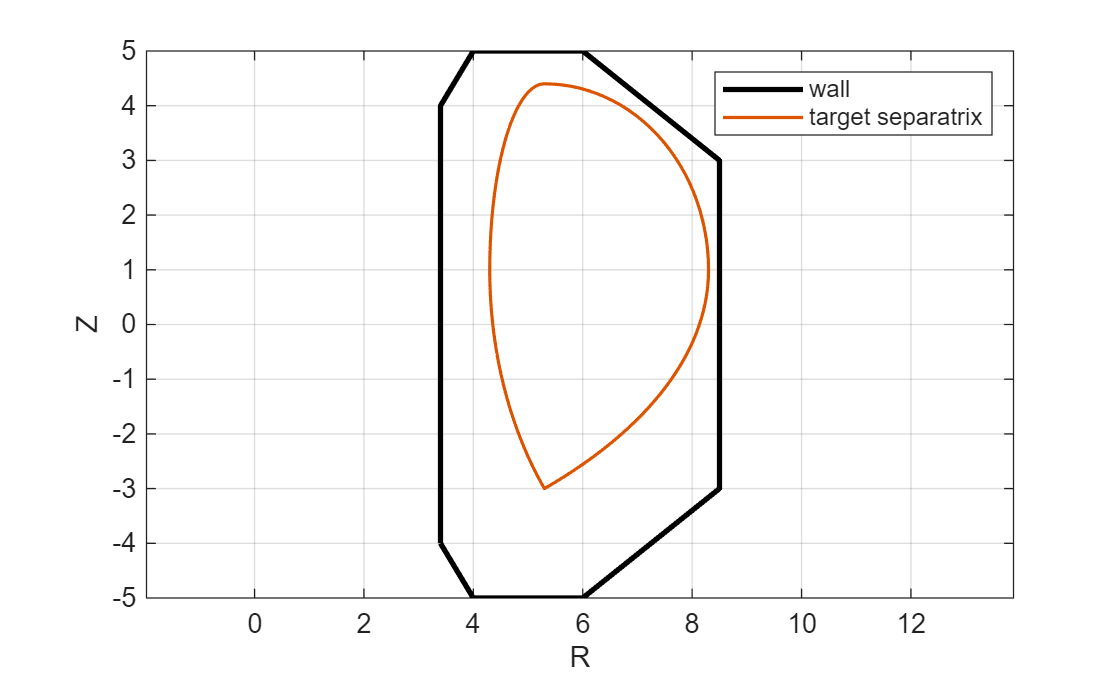

% shift the plasma center
equi = equi.import_configuration(geo, tok.config);
equi.config.separatrix.R0 = 6.3;
equi.config.separatrix.Z0 = 1;
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
figure
geo.plot_wall()
hold on
equi.plot_separatrix();
axis equal
legend("wall","target separatrix")

#### **Changing elongation**

The parameters `k1` and `k2` control the elongation of the upper and lower half of the plasma respectively. Increasing them makes the plasma taller and more "stretched" vertically.

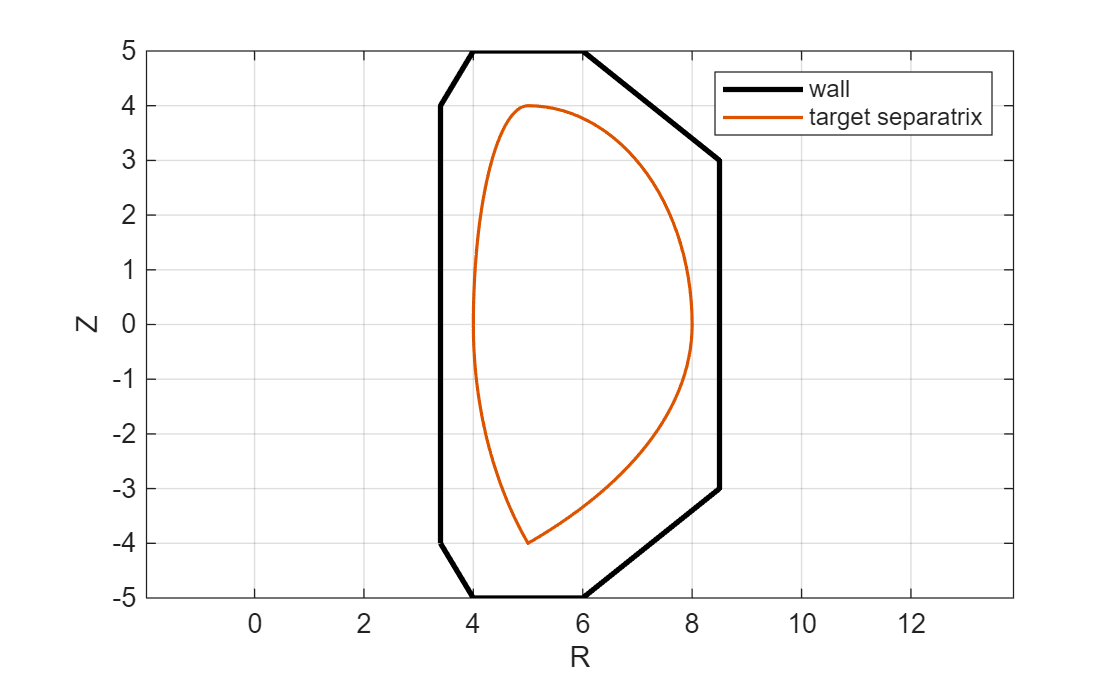

% increase elongation
equi = equi.import_configuration(geo, tok.config);
equi.config.separatrix.k1 = 2;
equi.config.separatrix.k2 = 2;
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
figure
geo.plot_wall()
hold on
equi.plot_separatrix();
axis equal
legend("wall","target separatrix")

#### **Changing triangularity**

The parameters `d1` and `d2` control the triangularity (how "D-shaped" the plasma is). Flipping their sign switches from positive to negative triangularity. Inner and outer angles defining the separatrix shape must also be switched accordingly.

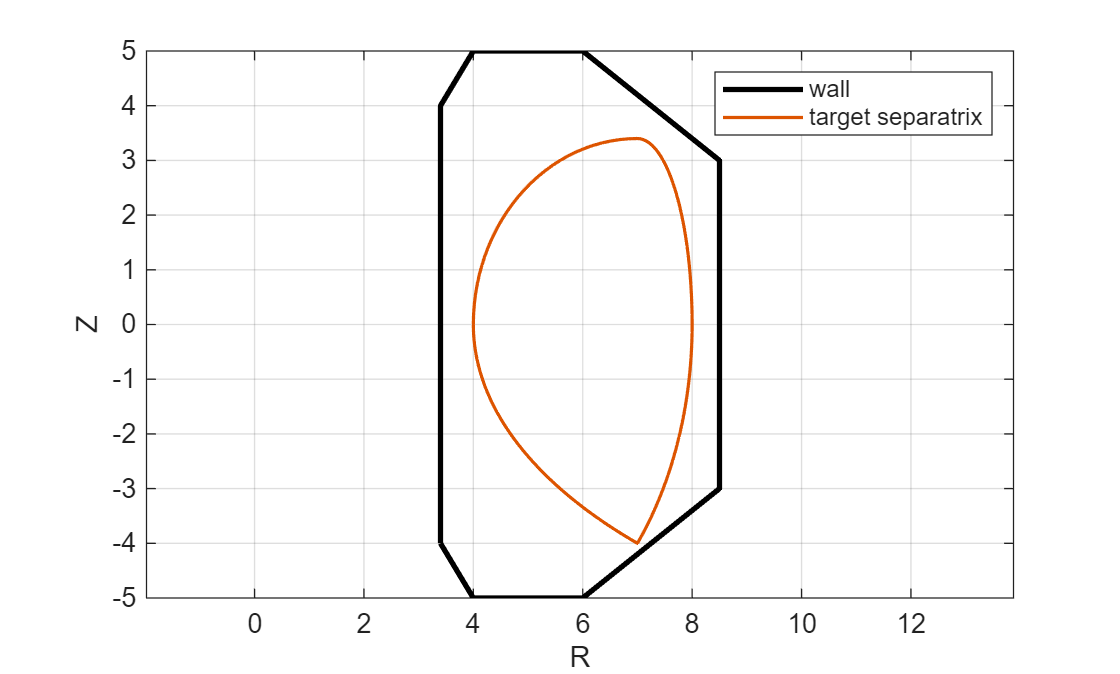

% switch to negative triangularity
equi = equi.import_configuration(geo, tok.config);
equi.config.separatrix.d1 = -0.5;
equi.config.separatrix.d2 = -0.5;
equi.config.separatrix.gamma_n_1 = 0; 
equi.config.separatrix.gamma_n_2 = pi/6;
equi.config.separatrix.gamma_p_1 = 0;
equi.config.separatrix.gamma_p_2 = pi/3;
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
figure
geo.plot_wall()
hold on
equi.plot_separatrix();
axis equal
legend("wall","target separatrix")

#### **A different standard scenario**

Instead of changing individual parameters, you can also load a whole different predefined scenario directly from `tokamak.scenario_upload`. For the default TokaLab machine, `separatrix = 2` gives a double-null configuration, and `separatrix = 3` gives a negative-triangularity configuration.

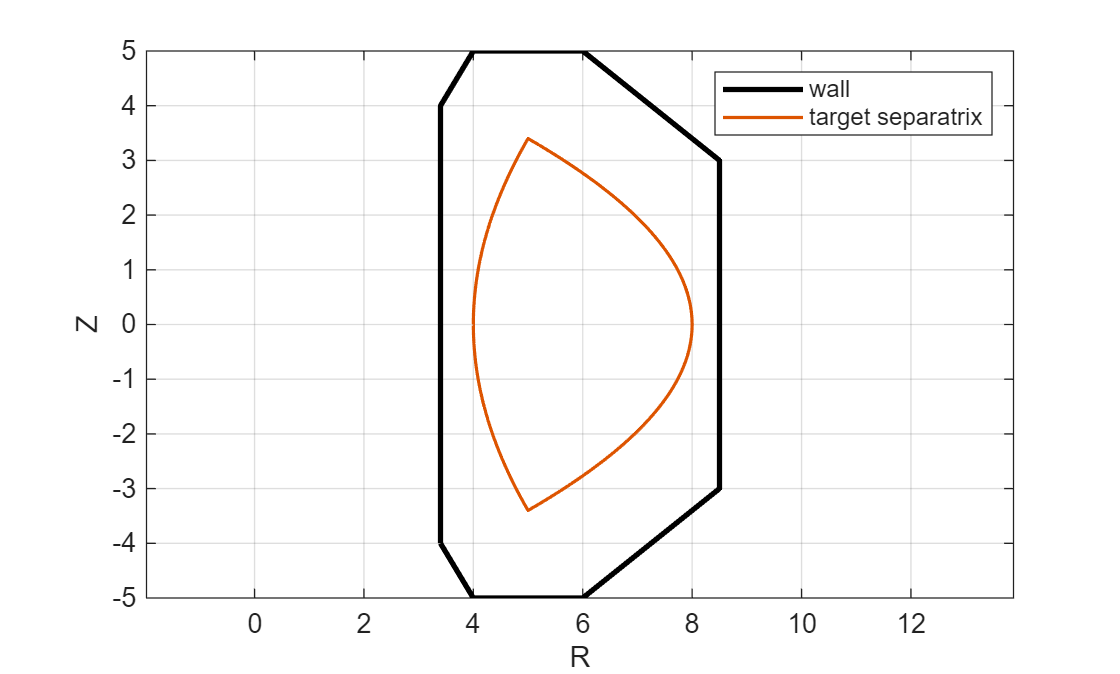

% load the double-null scenario instead of the default single-null one
tok = tok.scenario_upload(2,1);
equi = equi.import_configuration(geo,tok.config);
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
figure
geo.plot_wall()
hold on
equi.plot_separatrix();
axis equal
legend("wall","target separatrix")

### Changing the toroidal plasma current profile

The model used for the toroidal current density is controlled by `tok.config.toroidal_current` (mirrored in `equi.config.toroidal_current` after import). Unlike the separatrix, a change here only takes effect the next time you call `solve_equilibrium`, since the current profile enters directly into the Grad–Shafranov equation being solved.

#### **Changing the plasma current Ip**

`Ip` sets the total toroidal plasma current. Increasing its magnitude increases the source term in the Grad–Shafranov equation, and therefore changes how strongly the flux surfaces are compressed.

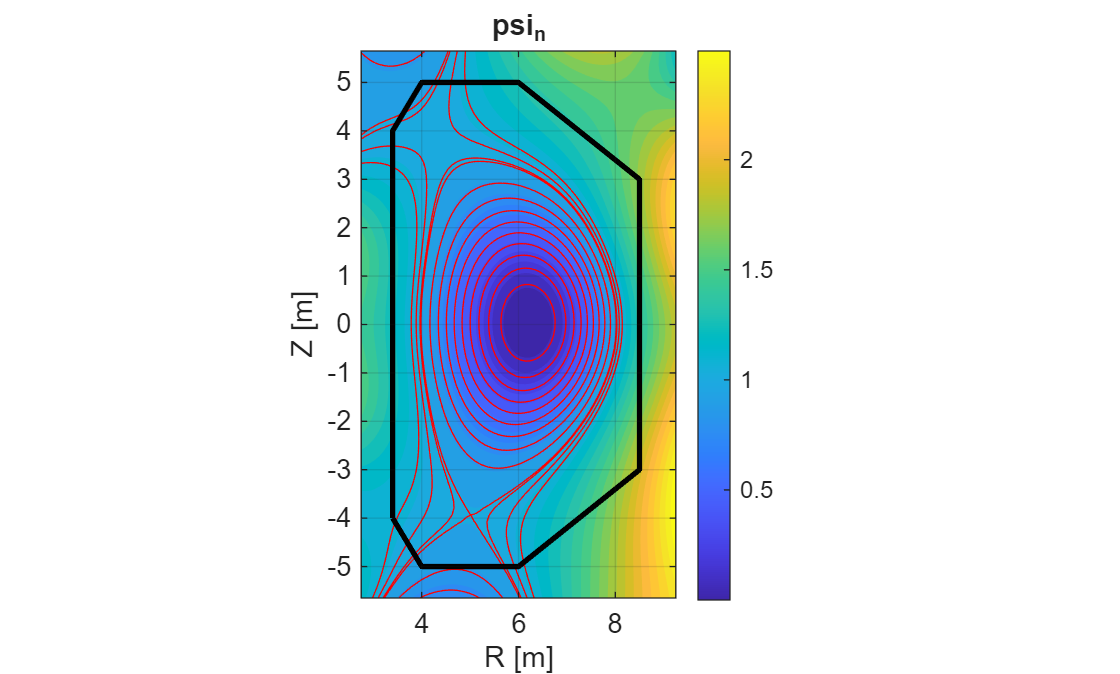

% increase the plasma current
tok = tok.scenario_upload(1,1);
equi = equi.import_configuration(geo,tok.config);
equi.config.GSsolver.Plotting = 0;
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
equi.config.toroidal_current.Ip = -15e6;
equi = equi.solve_equilibrium();
equi = equi.equi_pp();
figure
equi.plot_fields("psi_n",1)
hold on
geo.plot_wall()

#### **Changing the current peaking**

`alpha_1` and `alpha_2` control how peaked the current density profile is towards the magnetic axis. Larger values make the current more concentrated in the plasma core.

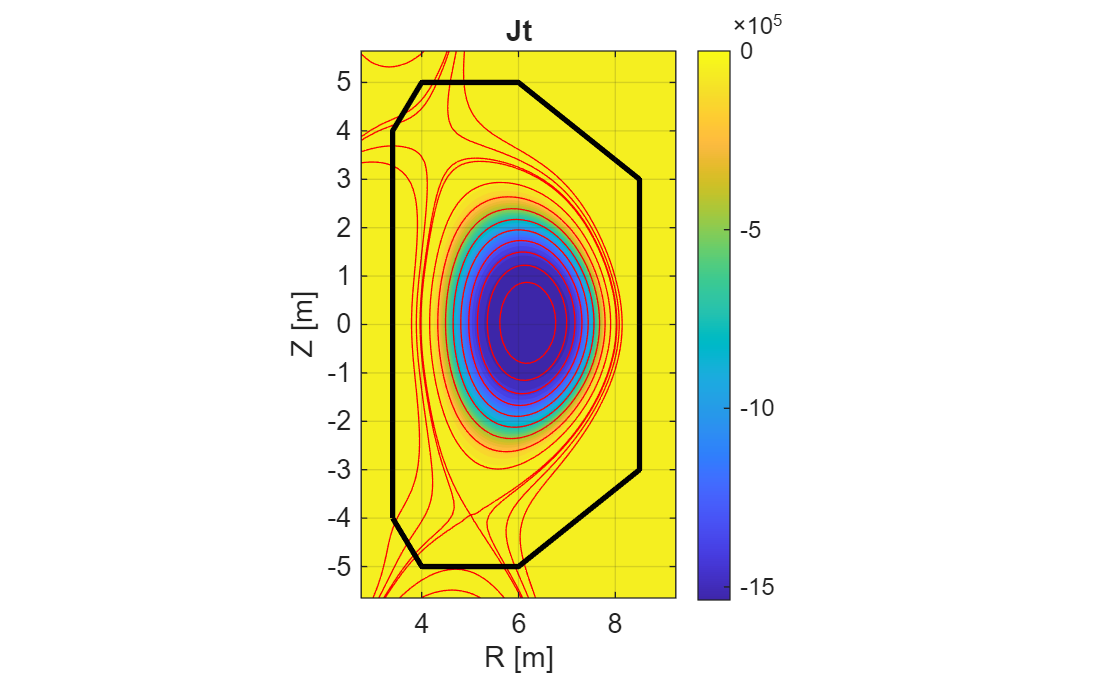

% make the current profile more peaked
equi.config.toroidal_current.alpha_1 = 3;
equi.config.toroidal_current.alpha_2 = 3;
equi = equi.solve_equilibrium();
equi = equi.equi_pp();
figure
equi.plot_fields("Jt",1)
hold on
geo.plot_wall()

#### **Using a hollow (reversed) current profile**

`equi.config.toroidal_current.method` selects the functional form used to relate the toroidal current to the poloidal flux. Method 2 implements a profile that peaks off-axis rather than at the magnetic axis, useful for exploring reversed-shear scenarios. Switching method requires reloading the scenario rather than editing the structure by hand, since the two methods expose different parameters.

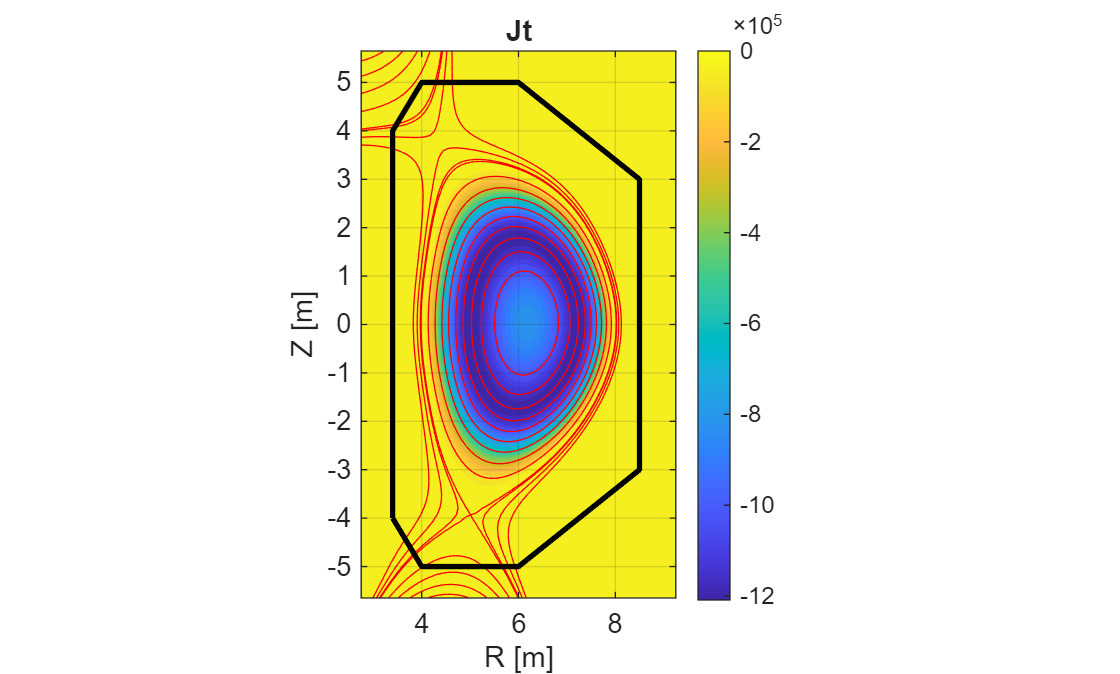

% load the reversed (off-axis peaked) current model
tok = tok.scenario_upload(1,2);
equi = equi.import_configuration(geo,tok.config);
equi.config.GSsolver.Plotting = 0;
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
equi = equi.solve_equilibrium();
equi = equi.equi_pp();
figure
equi.plot_fields("Jt",1)
hold on
geo.plot_wall()

### **Changing the density profile**

The kinetic profiles (electron/ion density and temperature) are controlled by `tok.config.kinetic` (mirrored in `equi.config.kinetic`). The density is modeled as a function of the normalized poloidal flux ψₙ:


$$n\left(\psi {\;}_n \right)=\left(n_0 -n_{\textrm{sep}} \right){\left(1-{\left(\min \left(\psi_{n\;} ,1\right)\right)}^{a_1 } \right)}^{a_2 }$$


where `n0` is the density on the magnetic axis, `nsep` is the density at the separatrix, and `a1`, `a2` shape how the profile drops from the core to the edge. The temperature is not set independently: it is derived afterwards from the pressure and the density profile you just defined, so changing the density will also change the temperature you see in the plots.

Since the kinetic profiles are computed only by `compute_profiles`, after changing any parameter you need to call it again (the equilibrium itself, ψ, does not need to be re-solved).

#### **Changing the core density**

`n0` sets the density on the magnetic axis.

% initialise the class tokamak
tok = tokamak;

% upload the geometry information of your tokamak
tok = tok.machine_upload();

TokaLab


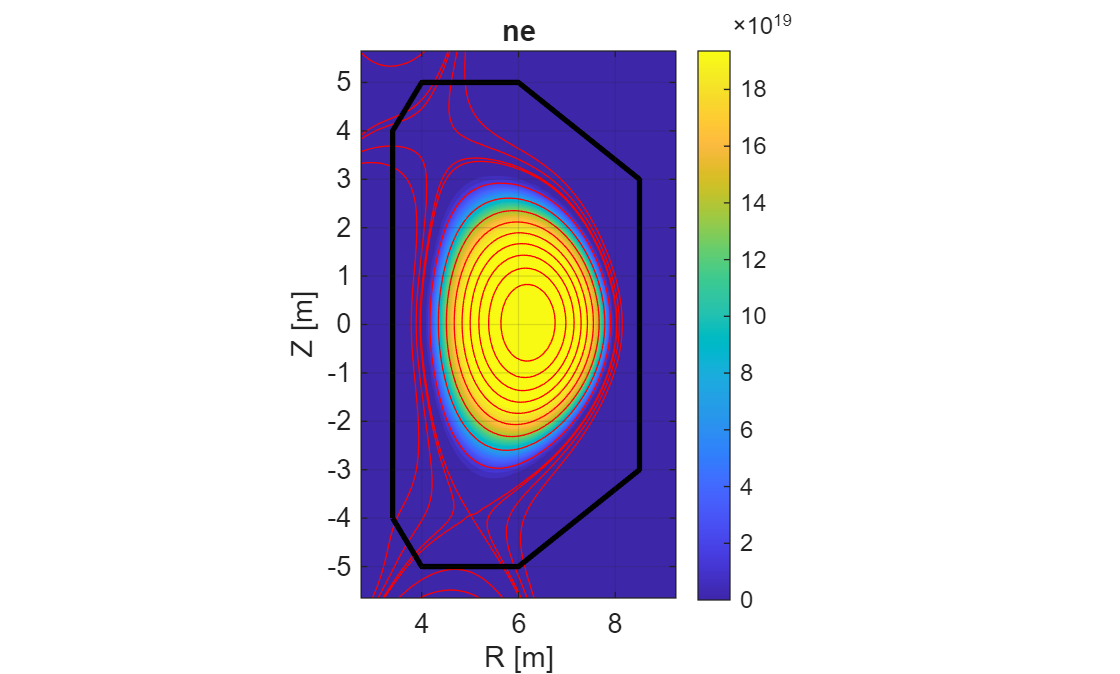

tok = tok.scenario_upload();
tok = tok.kinetic_upload();

% initialise the class geometry
geo = geometry;
geo = geo.import_geometry(tok);
geo = geo.build_geometry();
geo = geo.inside_wall();

% initialise the class equilibrium
equi = equilibrium;
equi = equi.import_configuration(geo,tok.config);
equi = equi.import_classes();
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);
equi.config.GSsolver.Plotting = 0;
equi = equi.solve_equilibrium();

% post processing (Opoint, Xpoint, LFCS)
equi = equi.equi_pp2();

% increase the core density
equi.config.kinetic.n0 = 2e20;
equi = equi.compute_profiles();
figure
equi.plot_fields("ne",1)
hold on
geo.plot_wall()

#### **Changing the edge density**

`nsep` sets the density at the separatrix. Note that the temperature profile reacts as well, since it is computed from `p./(2.*n.*e_charge)`.

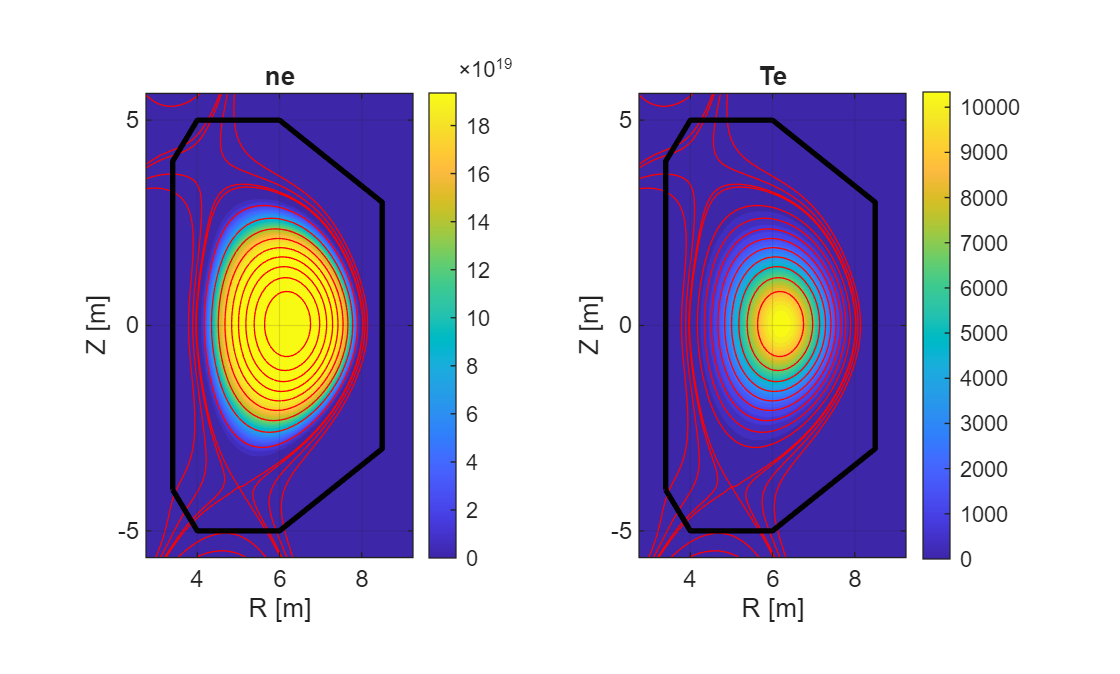

% raise the edge density
equi.config.kinetic.nsep = 5e17;
equi = equi.compute_profiles();

figure
subplot(1,2,1)
equi.plot_fields("ne",1)
hold on; 
geo.plot_wall()

subplot(1,2,2)
equi.plot_fields("Te",1)
hold on; geo.plot_wall()

#### **Changing the profile peakedness**

`a1` and `a2` shape how quickly the density falls from the core towards the edge. Larger values make the profile flatter in the core and steeper near the separatrix.

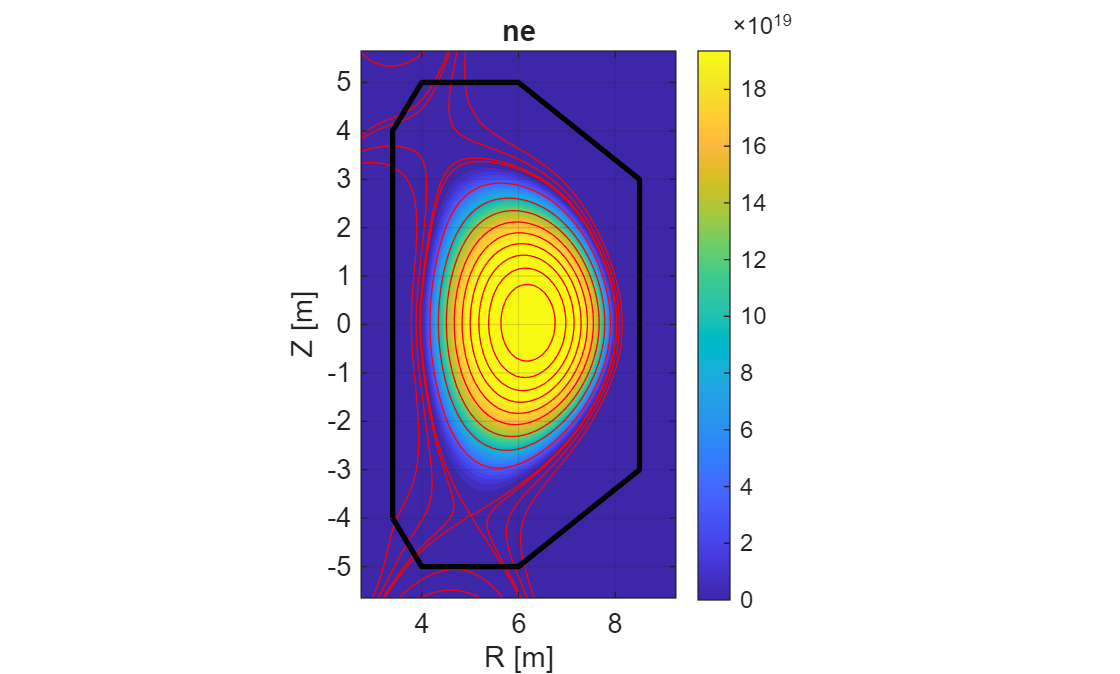

% make the density profile more peaked
equi.config.kinetic.a1 = 4;
equi.config.kinetic.a2 = 1.5;
equi = equi.compute_profiles();
figure
equi.plot_fields("ne",1)
hold on
geo.plot_wall()